# Import AUTOSAR Component to Simulink

Create Simulink® model from XML description of AUTOSAR software component.

## Import AUTOSAR Component from ARXML File to Simulink

Here is an AUTOSAR application software component that implements a controller in an automotive throttle position control system. The controller component takes input values from an accelerator pedal position (APP) sensor and a throttle position sensor (TPS). The controller translates the values into input values for a throttle actuator.

The component was created in an AUTOSAR authoring tool and exported to the file `ThrottlePositionControlComposition.arxml`.

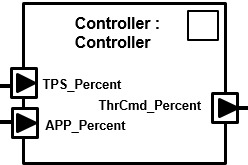

Use the MATLAB function [`createComponentAsModel`](docid:autosar_ref.mw_c5a5ec11-d9aa-4c75-9933-8258099589ea) to import the AUTOSAR XML (ARXML) description and create an initial Simulink representation of the AUTOSAR component. First, parse the ARXML description file and list the components it contains.

ar = arxml.importer('ThrottlePositionControlComposition.arxml');
names = getComponentNames(ar)

For the `Controller` software component, use `createComponentAsModel` to create a Simulink representation. 

createComponentAsModel(ar,'/Company/Components/Controller',...
    'ModelPeriodicRunnablesAs','AtomicSubsystem');

The function call creates a component model that represents an AUTOSAR application software component. An atomic subsystem represents an AUTOSAR periodic runnable, and an Initialize Function block represents an AUTOSAR initialize runnable. Simulink inports and outports represent AUTOSAR ports.

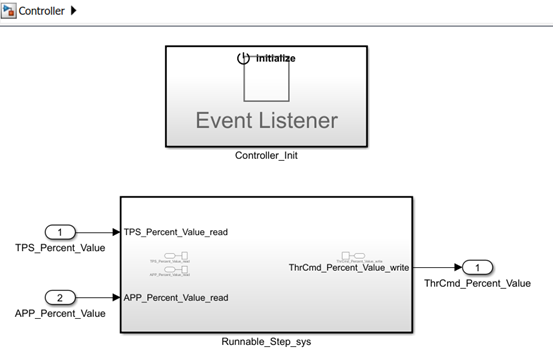

## Develop AUTOSAR Component Algorithm, Simulate, and Generate Code

After creating an initial Simulink representation of the AUTOSAR component, you develop the component. You refine the AUTOSAR configuration and create algorithmic model content.

For example, the `Runnable_Step_sys` subsystem in the  `Controller` component model contains an initial stub implementation of the controller behavior.

Here is a possible implementation of the throttle position controller behavior. (To explore this implementation, see the model `autosar_swc_controller`, which is provided with the example [Design AUTOSAR Components, Simulate, and Generate Code](docid:autosar_ug.mw_2cca1e20-3bca-4a1a-b954-8021e1cc3c51).) The component takes as inputs an APP sensor percent value from a pedal position sensor and a TPS percent value from a throttle position sensor. Based on these values, the controller calculates the *error*. The error is the difference between where the operator wants the throttle, based on the pedal sensor, and the current throttle position. In this implementation, a Discrete PID Controller block uses the error value to calculate a throttle command percent value to provide to a throttle actuator. A scope displays the error value and the Discrete PID Controller block output value over time.

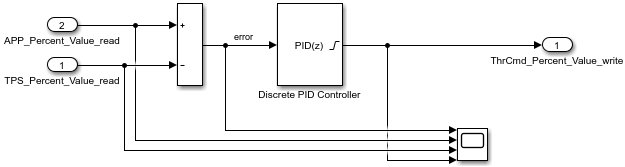

As you develop AUTOSAR components, you can:

- Simulate the component model individually or in a containing composition or test harness.

- Generate ARXML component description files and algorithmic C code for testing in Simulink or integration into an AUTOSAR run-time environment. (AUTOSAR code generation requires Simulink Coder and Embedded Coder.)

For more information on developing, simulating, and building AUTOSAR components, see example [Design AUTOSAR Components, Simulate, and Generate Code](docid:autosar_ug.mw_2cca1e20-3bca-4a1a-b954-8021e1cc3c51).

## Update AUTOSAR Component Model with Architectural Changes from Authoring Tool

Suppose that, after you imported the AUTOSAR software component into Simulink and began developing algorithms, architectural changes were made to the component in the AUTOSAR authoring tool.

Here is the revised component. The changes add a control override receive port and a throttle command override provide port. In the AUTOSAR authoring tool, the revised component is exported to the file `ThrottlePositionControlComposition_updated.arxml`.

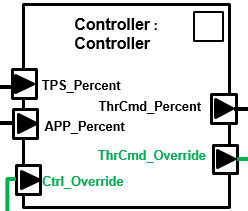

Use the MATLAB function [`updateModel`](docid:autosar_ref.mw_f3712731-00d9-4afa-91d6-6d42686c1505) to import the architectural revisions from the ARXML file. The function updates the AUTOSAR component model with the changes and reports the results.

ar2 = arxml.importer('ThrottlePositionControlComposition_updated.arxml');
updateModel(ar2,'Controller');

After the update, in the component model, highlighting indicates where changes occurred.

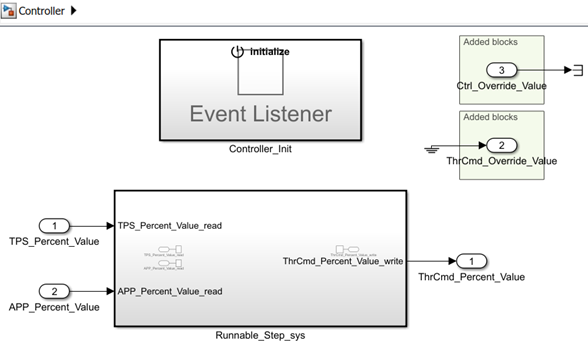

The function also generates and displays an HTML AUTOSAR update report. The report lists changes that the update made to Simulink and AUTOSAR elements in the component model. In the report, you can click hyperlinks to navigate from change descriptions to model changes.

Connect the added blocks, update the inports and outports inside the subsystem, and update the model diagram. For example:

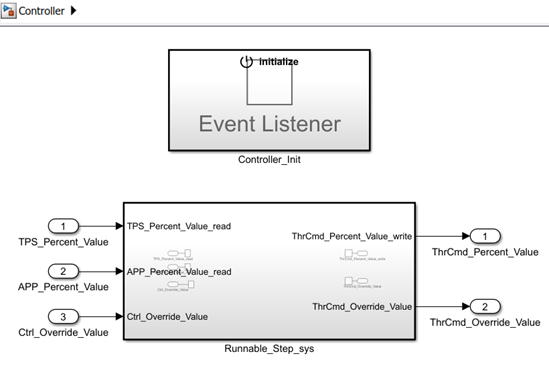

## Related Links

- [`createComponentAsModel`](docid:autosar_ref.mw_c5a5ec11-d9aa-4c75-9933-8258099589ea)

- [`updateModel`](docid:autosar_ref.mw_f3712731-00d9-4afa-91d6-6d42686c1505)

- [AUTOSAR Component Creation](docid:autosar_doccenter.mw_04becf9f-83c3-4914-924b-0816a0405b0c)

- [Import AUTOSAR Software Component Updates](docid:autosar_ug.buax917-1)

- [Design AUTOSAR Components, Simulate, and Generate Code](docid:autosar_ug.mw_2cca1e20-3bca-4a1a-b954-8021e1cc3c51)

*Copyright 2018-2019 The MathWorks, Inc.*